# 6. Image Regression

load imageRegressionData.mat

## What is Regression?

Regression is another task that can be accomplished with deep learning. *Regression* refers to assigning continuous response values to data, instead of discrete classes.

One example of image regression is correcting rotated images. The input data is a rotated image, and the known response is the angle of rotation.

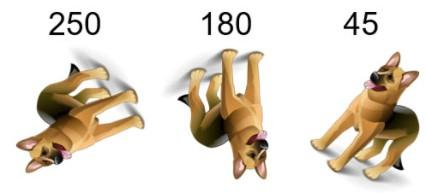

You will build a network that corrects the color in images. 

A set of images have been modified by changing their red, green, and blue channels. The response for each modified image is three numeric values that correspond to the intensity increase or decrease of the corresponding channel.

### Peek into the data

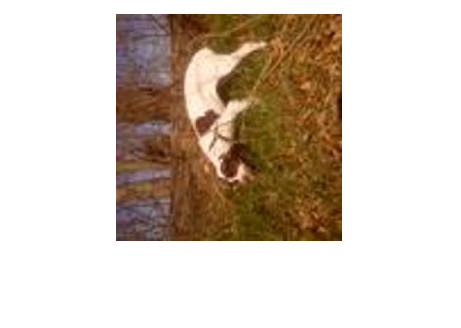

imshow(imread(trainingData.File{1}))

## Transfer Learning for Image Regression

###     Modify the GoogLeNet for regression using Deep Network Designer App

- Replace the `fullyConnectedLayer` 

- Delete the `softmaxLayer`

###     Prepare the data

trainds = augmentedImageDatastore([224,224],trainingData);
testds = augmentedImageDatastore([224,224],testData);

## Train the Network 

opts = trainingOptions("adam","InitialLearnRate",0.0001,...
    "MaxEpochs",30,"Plots","training-progress","Metrics","rmse");
newNet = trainnet(trainds,net_1,"mse",opts)

## Evaluate the Network

Predict the response for all images in the test data and calculate the root mean squre error (RMSE) for the test data set.

testPred = minibatchpredict(newNet, testds)

testPred = 20×3 single 행렬
    1.1408    2.4595    1.2142
   -8.8332    5.9905   -7.2771
   -8.3778   -5.8312    7.2475
   -3.8583    8.8080   -3.6876
   -1.3616    9.0029    3.5909
    2.2169   -7.8791    2.8241
   -7.5833   14.2604   -4.3872
    6.0822    0.0065    3.1386
    0.0344    6.6407   -5.3073
   -4.2587    6.7797   -2.9537


rgbGT = testData.Color

rgbGT =      8   -13   -14
    -1    43     5
   -15   -11    24
     7    21   -11
   -51    28     6
     4   -42    28
     0    10   -22
    49   -22    20
    19    28   -19
   -21    47   -23


err = rgbGT - testPred

err = 20×3 single 행렬
    6.8592  -15.4595  -15.2142
    7.8332   37.0095   12.2771
   -6.6222   -5.1688   16.7525
   10.8583   12.1920   -7.3124
  -49.6384   18.9971    2.4091
    1.7831  -34.1209   25.1759
    7.5833   -4.2604  -17.6128
   42.9178  -22.0065   16.8614
   18.9656   21.3593  -13.6927
  -16.7413   40.2203  -20.0463


rootMeanSquaredError = sqrt(mean(err.^2))

rootMeanSquaredError = 1×3 single 행 벡터
   21.3606   19.7070   15.3676


% rootMeanSquaredError = rmse(rgbGT, testPred)

## Correct the color

Use the network to correct the rgb value of the first test image and display the corrected image.

testImage = imread(testData.File{10})

testImage = 227×227×3 uint8 배열
testImage(:,:,1) =

   177   156   142   163   173   169   178   165   158   142   150   153   158   154   135   138   149   153   152   147   143   147   156   162   157   154   156   139   143   161   148   139   153   187   127   102   146   133   121   161   163   117    52    22    37    52    77   115   140   164   141   113   132   126    67    18    21    23    51   140   195   179   175   187   169   167   152   144   166   175   155   131   106   135   170   139   140   137   140   125   124   140   146   142   142   150   152   145   129   118   126   136   134   144   144   123   117   114   126   125   109   121   115    69    57    40    50    67    79   125   158   147   149   145   131   135   116    85    96   109   119   116   133   138   116   111   125   127   121   157   181   171   159   159   155   144   133   126   138   164   174   163   161   173   163   168   162   161   151   148   162   147   159   152   142   132   142   163 

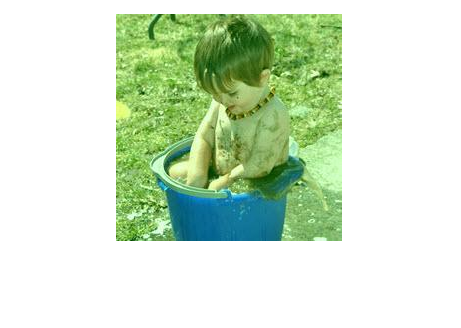

imshow(testImage)

rgb = testPred(10,:)

rgb = 1×3 single 행 벡터
   -4.2587    6.7797   -2.9537


correctedImage = correctColor(testImage,rgb)

correctedImage = 227×227×3 uint8 배열
correctedImage(:,:,1) =

   181   160   146   167   177   173   182   169   162   146   154   157   162   158   139   142   153   157   156   151   147   151   160   166   161   158   160   143   147   165   152   143   157   191   131   106   150   137   125   165   167   121    56    26    41    56    81   119   144   168   145   117   136   130    71    22    25    27    55   144   199   183   179   191   173   171   156   148   170   179   159   135   110   139   174   143   144   141   144   129   128   144   150   146   146   154   156   149   133   122   130   140   138   148   148   127   121   118   130   129   113   125   119    73    61    44    54    71    83   129   162   151   153   149   135   139   120    89   100   113   123   120   137   142   120   115   129   131   125   161   185   175   163   163   159   148   137   130   142   168   178   167   165   177   167   172   166   165   155   152   166   151   163   156   146   136   

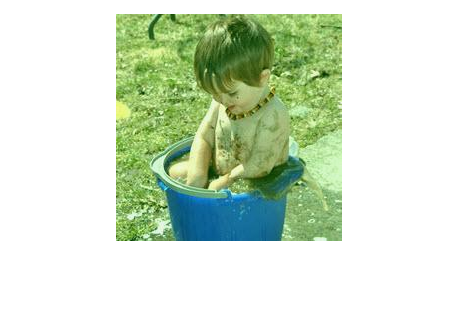

imshow(correctedImage)

function fixedim = correctColor(im, rgb)
    fixedim = uint8(single(im) - reshape(rgb,[1 1 3]));
end

